# ECEN5463 | HW2

Collin Thornton

## Problem 1

syms x1 x2

X = [x1;x2];
f = [x1 + x2 - x1*(x1^2+x2^2);
     -2*x1 + x2 - x2*(x1^2 + x2^2)];

sol = solve(f==0, 'ReturnConditions', true);
eq_points = [sol.x1, sol.x2];
simplify(eq_points)

$$ans = \begin{array}{l} \left(\begin{array}{cc} -\sigma_{1} & -\sigma_{3}\\ \sigma_{2} & -\sigma_{4}\\ 0 & 0\\ \sigma_{1} & \sigma_{3}\\ -\sigma_{2} & \sigma_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{1-\sqrt{2}\,\mathrm{i}}\,\mathrm{i}\\ \sigma_{2}=\sqrt{1+\sqrt{2}\,\mathrm{i}}\,\mathrm{i}\\ \sigma_{3}=\sqrt{2-2\,\sqrt{2}\,\mathrm{i}}\\ \sigma_{4}=\sqrt{2+2\,\sqrt{2}\,\mathrm{i}} \end{array}$$

Must find all values of $r \in \mathbb{R}$ such that the ball of radius $\bar B(0,r) \subset \mathbb{R}^m$ with resepct to $\dot x = f(x), x \in \mathbb{R}^m$ implies $\forall x \in \partial B(0,r), f^T(x)n(x)\leq0$

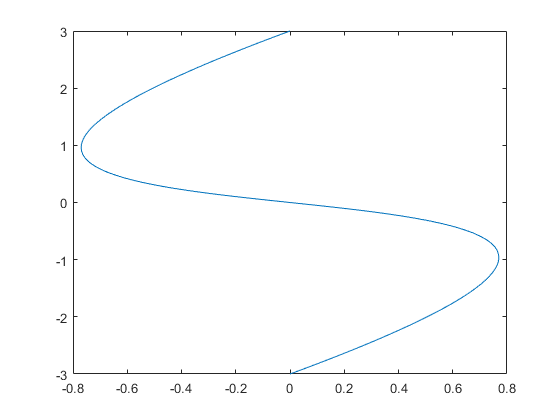

figure()
t = linspace(-1,1,500);

f1 = @(x1,x2) x1 + x2 - x1.*(x1.^2+x2.^2);
f2 = @(x1,x2) -2.*x1 + x2 - x2.*(x1.^2 + x2.^2);

plot(f1(t,t), f2(t,t));

## Problem 2 

### 2-1 Show that the system $\dot{x} =x^2$ admits solutions that blow up to infinity in finite time

## Problem 3 Prove wheter the following functions are continous from $\mathbb{R}$ to $\mathbb{R}$

Continuous functions $f\left(x\right)$ must satisfy the following points to be called piecewise continous:

- $t\to f\left(t,x\right)$contains a finite number of discontinuties at $t\in J$

- 
$$\forall \;t\in J,\lim_{h\to 0^+ } f\left(t+h,x\right)\;\mathrm{and}\;\lim_{h\to 0^- } \;f\left(t+h,x\right)\;\mathrm{exist}\;\mathrm{and}\;\mathrm{are}\;\mathrm{finite}$$


### 3-1 $f\left(x\right)=\max \left(0,x\right)$

syms x

f = x*heaviside(x);
disc = feval(symengine, 'discont', f, x)

$$disc = \left\{0\right\}$$

There is only 1 discontinuous point

limit(f,x,0,'left')

$$ans = 0$$

limit(f,x,0,'right')

$$ans = 0$$

subs(f,x,0)   

$$ans = 0$$

Both limits exist and are equivalent. Therefore $f\left(x\right)=\max \left(0,x\right)$ is **continous**.

### 3-2 $f\left(x\right)=\left\lbrace \begin{array}{ll}
\sin \left(x\right) & x>0\\
0 & x\le 0
\end{array}\right.$

syms x
f = sin(x)*heaviside(x);

disc = feval(symengine, 'discont', f, x)

$$disc = \left\{0\right\}$$

There is only 1 discontinuous point

limit(f,x,0,'left')

$$ans = 0$$

limit(f,x,0,'right')

$$ans = 0$$

subs(f,x,0)

$$ans = 0$$

Both limits exist and are equivalent. Therefore $f\left(x\right)=\left\lbrace \begin{array}{ll}
\sin \left(x\right) & x>0\\
0 & x\le 0
\end{array}\right.$ is **continous**.

### 3-3 $f\left(x\right)=\mathrm{sgn}\left(x\right)=\left\lbrace \begin{array}{ll}
1 & x>0\\
-1 & x<0\\
0 & x=0
\end{array}\right.$

syms x

f = piecewise(x<0, -1, x==0, 0, x>0, 1);

disc =  feval(symengine, 'discont', f, x) 

$$disc = \left\{0\right\}$$

There is only one discontinous point

limit(f,x,0,'left')

$$ans = -1$$

limit(f,x,0,'right')

$$ans = 1$$

subs(f,x,0)                        

$$ans = 0$$

Both limits exist, though they are not equivalent. There $f\left(x\right)=\mathrm{sgn}\left(x\right)$ is **not continuous**. (Though it is piecewise continuous)

## Problem 4

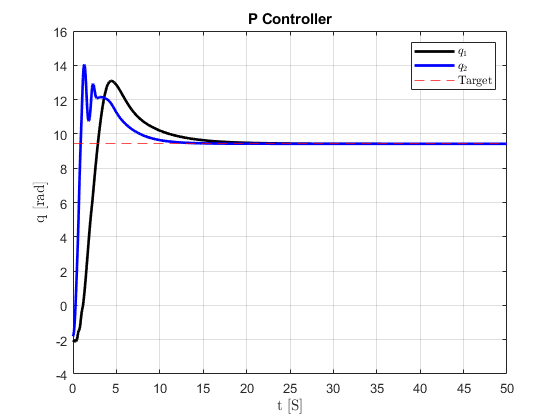

% Set the initial condition for the state and the time interval for integration

% x = [q1;q2;dq1;dq2];
x0 = 10*(rand(4,1)-0.5);
tspan = linspace(0,50,1000);

P = [3.473;0.196;0.242];

% Solve the ode using 'ode45'.
[t,x] = ode45(@(t,x) closedLoopDynamics(t,x,P,"P"), tspan, x0);
% Read the documentation of 'ode45' to find out the format of the output,
% x, so that you can generate the required plots.

figure()

plot(t,x(:,1), '-k', "LineWidth", 2)
hold on;
plot(t,x(:,2), '-b', "LineWidth", 2)
yline(3*pi, '--r')

title("P Controller")
grid on
legend("$q_1$", "$q_2$", "Target", "Interpreter", "latex")
xlabel("t [S]", "Interpreter", "latex")
ylabel("q [rad]", "Interpreter", "latex")

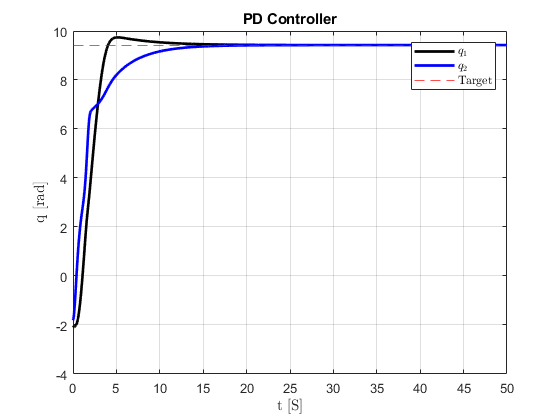

% Solve the ode using 'ode45'.
[t,x] = ode45(@(t,x) closedLoopDynamics(t,x,P,"PD"), tspan, x0);
% Read the documentation of 'ode45' to find out the format of the output,
% x, so that you can generate the required plots.

figure()

plot(t,x(:,1), '-k', "LineWidth", 2)
hold on;
plot(t,x(:,2), '-b', "LineWidth", 2)
yline(3*pi, '--r')

title("PD Controller")
grid on
legend("$q_1$", "$q_2$", "Target", "Interpreter", "latex")
xlabel("t [S]", "Interpreter", "latex")
ylabel("q [rad]", "Interpreter", "latex")



% FUNCTIONS
%
% The last argument P in all the functions below is used to pass parameters
% to the function if needed. For example, if you want to simulate multiple
% robots with different friction coefficients in a for loop, you can set
% the values of friction coefficients in P at the beginning of this script
% as P.Fs1 = 8.45 and P.Fs2 = 2.35 instead of hard-coding them inside the
% function. Another example would be to store control gains in P instead of
% hardcoding them in the control function.
%
% If you do not need to pass any parameters, remove P from all functions.


function x_dot = closedLoopDynamics(t, x, P, c)
    % This function "simulates" the behavior of a two-link robot under the
    % controller given by the 'control' function.
    x_dot = openLoopDynamics(t, x, control(t,x,c), P);
end


function x_dot = openLoopDynamics(t, x, u, P)
    % This function "simulates" the behavior of a two-link robot
    % manipulator using a model in the state space form. 
    %
    % TODO: Use the given equations to compute x_dot using t, x, and u
    M = [P(1)+2*P(3)*cos(x(2)), P(2)+P(3)*cos(x(2));
         P(2) + P(3)*cos(x(2)), P(2)];
    V = [-P(3)*sin(x(2))*x(4), -P(3)*sin(x(2))*(x(3)+x(4));
         P(3)*sin(x(2))*x(3), 0];
    F = [8.45*tanh(x(3)); 2.35*tanh(x(4))];
    
    ddq = M\(u - V*x(3:4) - F);
    x_dot = [x(3:4);ddq];
end

function u = control(t, x, c)
    % This function calculates the control signal (a vector containing the
    % torque commands for the two joints of the two-link robot) as a
    % function of time and state
    % Use the given equations to compute u using from t and x here
    persistent E t0 e0
    
    if isempty(E)
        E = zeros(2,1);
    end
    if isempty(t0)
        t0 = 0;
    end
    if isempty(e0)
        e0 = 0;
    end
    
    e = [3*pi;3*pi] - x(1:2);
    E = E+e;
    dt = t-t0;
    de = e-e0;
        
    t0 = t;
    e0 = e;
    
    kP = [2;1];
    P = kP.*e;
        
    if strcmp(c,'P')    
        u = P;
    elseif strcmp(c,'PD')
        kD = [1;1];
        if dt == 0
            D = [0;0];
        else
            D = kD.*(de/dt);
        end
    
        u = P + D;
    else
        kI = [0;0];
        I = kI.*(E*(dt));
        
        kD = [1;1];
        if dt == 0
            D = [0;0];
        else
            D = kD.*(de/dt);
        end
    
        u = P + I + D;    
    end
end